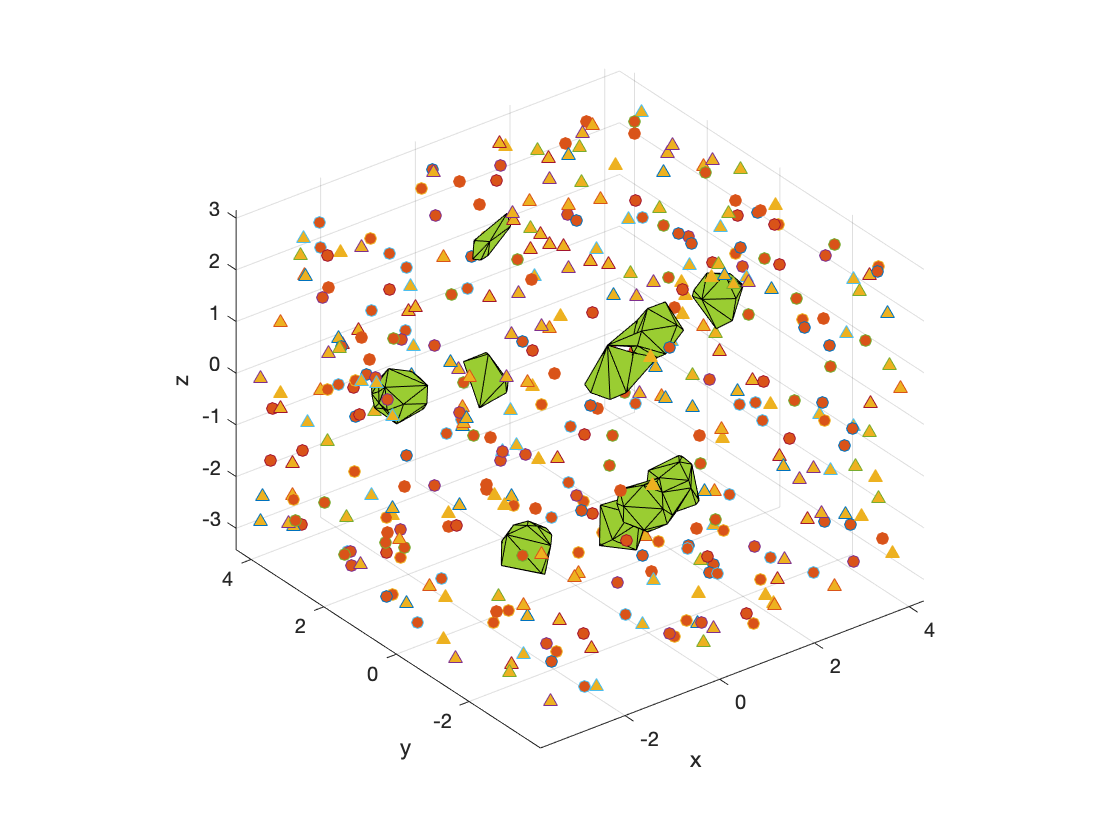

% load('Full_test_data.mat')
% size(nodes)

clear
% Build Obstacles:
[boundaries, n_obs_vertices, obs_vertices] = Obstacles(10);
hold on

KD_time = [];
min_dist_time = [];
n_nodes = [];
for n = 1:10:2000 % Random trees of size n
    
    clear nodes
    [r_start, r_end, search_boundaries] = StartEnd_Coor(boundaries);
    
    temp_KD_time      = [];
    temp_sq_norm_time = [];
    for ite = 1:20 % iterate 20 times to get a mean
        pt_start.pose                       = r_start;
        pt_start.cost                       = 0;
        pt_start.RRT_parentIdx              = 0;
        pt_start.KDTree_parentIdx           = 0;
        pt_start.KDTree_LchildIdx           = NaN;
        pt_start.KDTree_RchildIdx           = NaN;
        nodes(1)                            = pt_start;
        
        % Build a tree of size n:
        for j = 1:n
            % Random point of interest
            PT = Random_point(search_boundaries); 
            
            % Just benchmark KD NN func, dont care RRT* variables
            pt_new.cost          = NaN;
            pt_new.RRT_parentIdx = NaN;
            pt_new.pose          = PT;
            [pt_new, nodes]      = KD_tree_insert(pt_new, nodes, 1, 'NA', nodes(1).KDTree_parentIdx, 0); % Initial childIdx = 1, current dim = 0 (will shift to +1 inside)
       
            nodes = [nodes pt_new];
        end
        
        POI = Random_point(search_boundaries);
        % KD NN
        tic
        [min_dist, min_idx] = KD_Nearest_Neighbour(POI, nodes);
        a = toc;
        
        % Sq norm
        tic
        dist_min = min(dist_metric(POI, nodes, 'custom_dist'));
        b = toc;
        
        temp_KD_time      = [temp_KD_time, a];
        temp_sq_norm_time = [temp_sq_norm_time, b];
        assert(dist_min == min_dist)
        
        clear nodes
    end
    KD_time = [KD_time, mean(temp_KD_time)];
    min_dist_time = [min_dist_time, mean(temp_sq_norm_time)];
    n_nodes = [n_nodes, n+1];
end

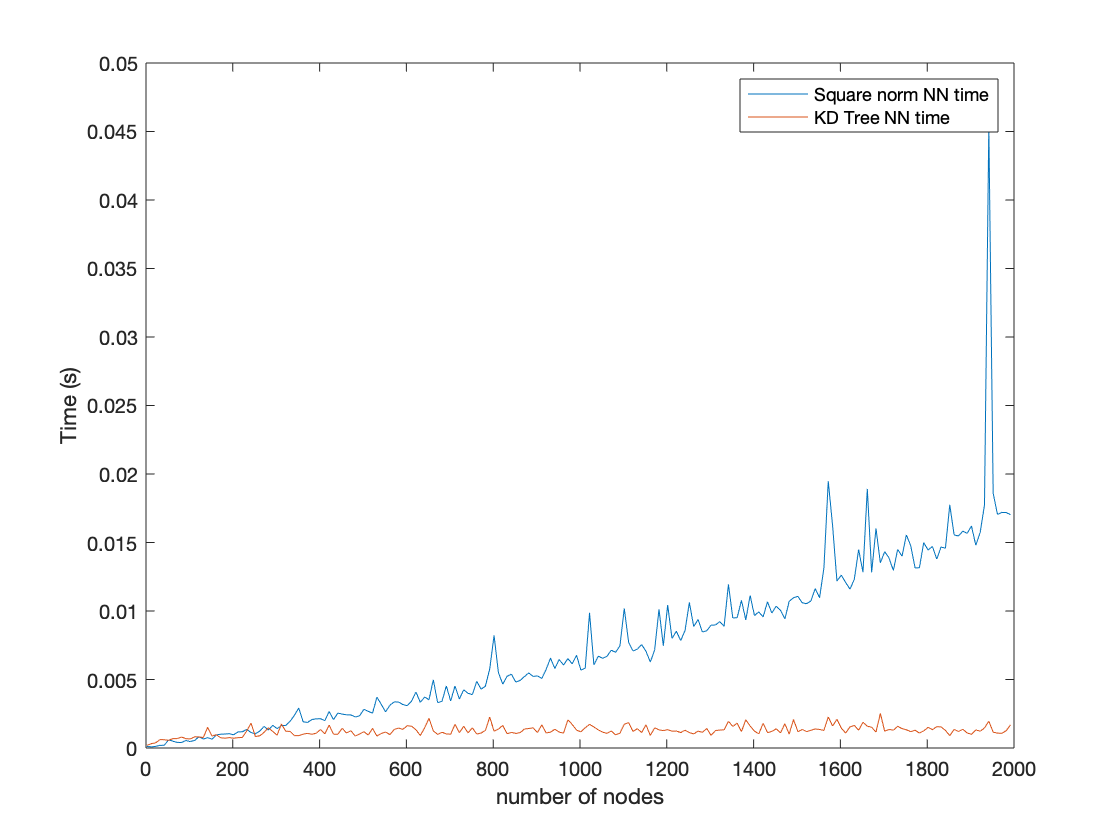

hold off 

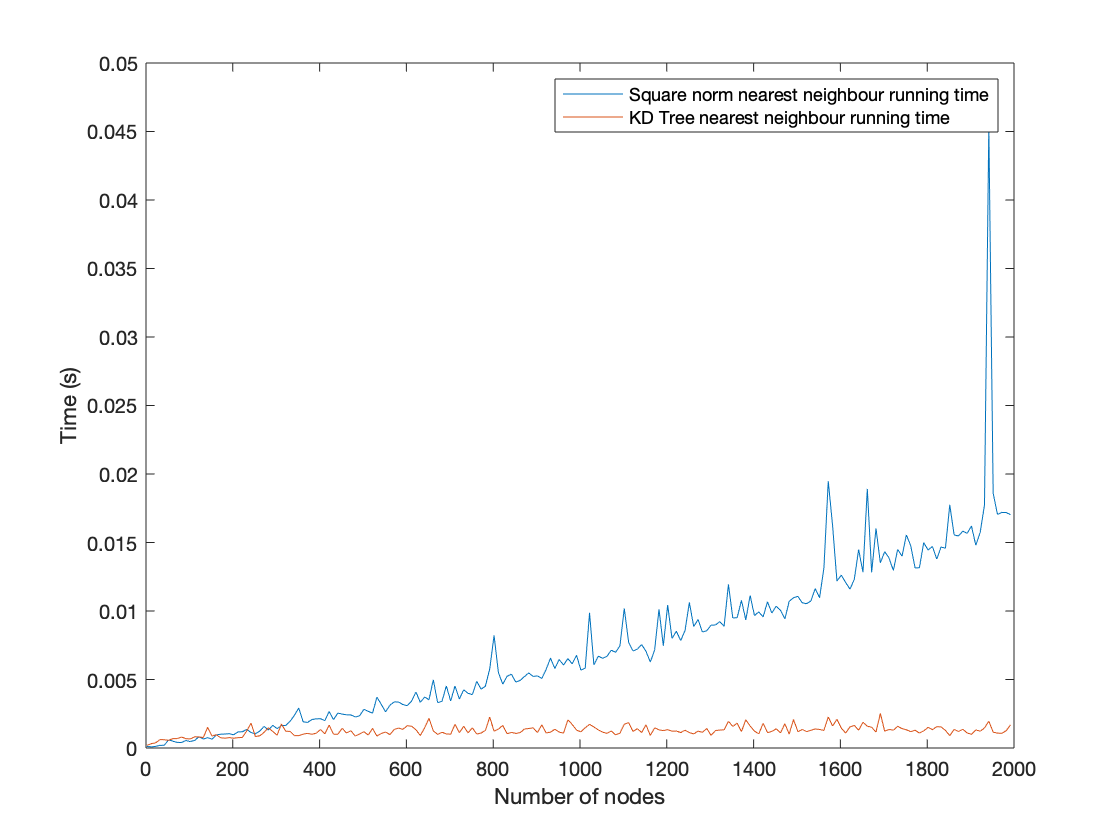

plot(n_nodes, min_dist_time)
hold on
plot(n_nodes, KD_time)
legend({'Square norm nearest neighbour running time', 'KD Tree nearest neighbour running time'})
xlabel('Number of nodes')
ylabel('Time (s)')

% POI = [1.8574    2.3649   -3.2877];
% POI = [2.5580   -1.6455    0.1085];
% [min_dist, min_idx] = KD_Nearest_Neighbour(POI, nodes, 0, 1, inf, 0)
% dist_min = min(dist_metric(POI, nodes, 'custom_dist'))